# Project “Vessel Detection in Endoscopic Data”

Name: Tessa Vogt

Matrikelnummer: 7216463

## Aufgabenstellung:

- Ansatz zur automatischen Erkennung von Gefäßen auf laparoskopischen Bildern

- Entwicklung der Liniensegmentierung/Skelettierung

## Bildverarbeitung

- Verarbeitung und Analyse von digitalen Bildern, um Informationen zu extrahieren, visuelle Eigenschaften zu modifizieren oder bestimmte Aufgaben zu erfüllen

- Filter auf das Bild anwenden zur Vorbereitung der Bilddaten für die Segmentierung

- Glättung

- Kanten hervorheben

- Kontrastverstärkung

### Filter

- eine Funktion oder ein Algorithmus, der auf ein Eingangssignal angewendet wird, um das Ausgangssignal zu modifizieren oder bestimmte Eigenschaften des Signals zu extrahieren

- Moadische Operationen: werden auf ein einzelnes Element angewendet (z.B. Helligkeit oder Kontrastverstärkung)

- Diadische Operationen: werden auf Paare von Elementen angewendet (z.B. Addieren von 2 Bildmatizen)

- Räumliche (Spatial) Operatoren: werden auf alle benachbarte Elemente angewendet (z.B. Smoothing-Filter oder Kantenverstärkung)

- Morphologische Operatoren: eine Teilmenge von Pixeln des Eingangsbildes hat Auswirkung auf ein einziges Pixel des Ausgangsbildes (z.B. Erosion und Dilation) 

#### Gauss-Filter

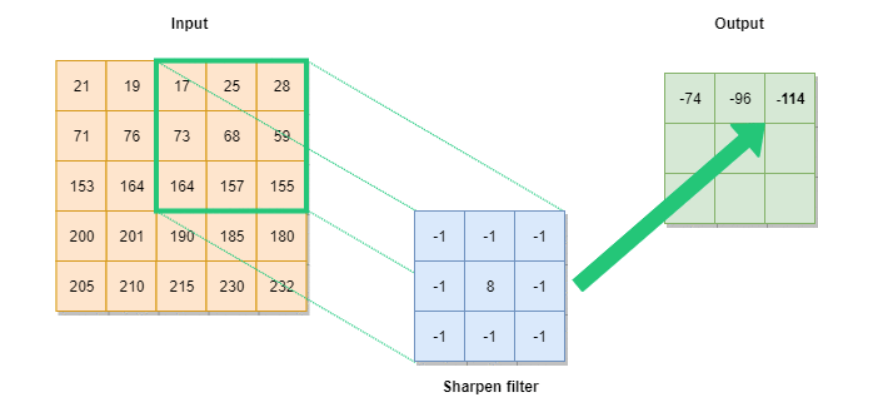

- wird zum Glätten von Bildern verwendet

- basiert auf der Gauss'schen Verteilung und verwendet eine Gewichtungsfunktion, um benachbarte Pixel eines Bildes zu berücksichtigen

- jedem Pixel im Bild wird ein neuer Wert zugeweist, der durch eine gewichtete Durchschnittsberechnung der umliegenden Pixel bestimmt wird

- Gewichtungen wird basierend auf der Entfernung zum betrachteten Pixel berechnet (Pixel, die näher am betrachteten Pixel liegen, erhalten ein höheres Gewicht)

- Effekt: Rauschen und feine Details im Bild  werden reduziert -> Unschärfe, da er die Unterschiede zwischen benachbarten Pixeln verringert

- Padding: Auffüllen den Bildrandbereichs mit zusätzlichen Pixeln, um dunklen Rand um gefiltertes Bild zu vermeiden

#### Isobel-Filter zur Kantenerkennung

- Sobel-Operator: Berechnung der Gradienten (Vektor in Richtung der größten Steigung) im Bild

- Magnitude = Länge des Gradienten = Größe der Steigung

- besteht aus zwei separaten Filterkernen, die horizontal und vertikal ausgerichtet sind

- horizontale Sobel-Operator: erkennt Kanten, die in horizontaler Richtung verlaufen

- vertikale Sobel-Operator: erkennt Kanten, die in vertikaler Richtung verlaufen

- Problem: Sobel-Berechnung führt zu Rauschen im Bild -> Glättung

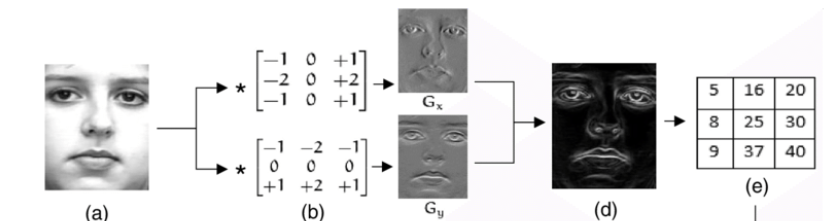

#### Closing

- Closing-Operator: Lücken in Objekten schließen oder Artefakte zu eliminieren 

- Dilatation (Ausdehnung) des Bildes 

- Erosion (Verkleinerung) des resultierenden Bildes

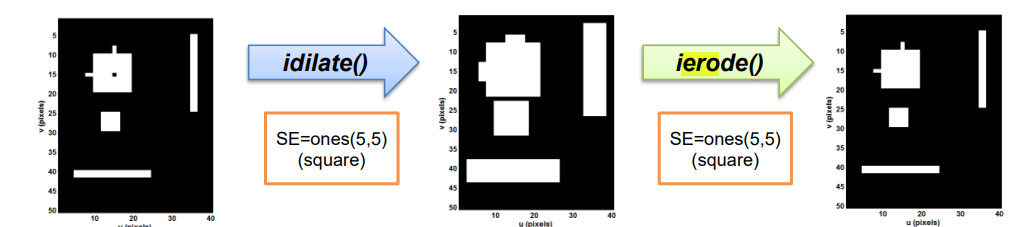

### Segmentierung

- Bild in verschiedene Regionen oder Objekte aufgeteilen

- ähnliche Pixel oder Bildbereiche basierend auf bestimmten Kriterien gruppieren oder voneinander trennen

- tristim2cc()

- kmeans()

- colorkmeans()

#### Berechnung der chromatischen Koordinate

- chromatischen Koordinaten (RGB-Farbmerkmale eines Pixels unabhängig von Helligkeit) nutzen zur Gruppierung bestimmter Farbwerte

- mit Hilfe von Threshold nur bestimmte Farbwerte extrahieren

#### Clustering-Algorithmen

- automatische Bildsegementierung die Bilder aufgrund ihrer Farbwerte in Cluster gruppiert

- jeder Pixel wird dem Cluster zugewiesen, dessen zentraler Farbwert ihm am nächsten liegt

- Unterschied zwischen kmeans- und colorkmeans-Funktion: colorkmeans berücksichtigt auch die räumlie Pixelposition im Bild -> Farbregionen und räumliche Zusammengehörigkeit der Pixel werden berücksichtigt

## Quellen

Bildquelle Gauss-Filter: [Coding Gaussian Blur Operation In Python From Scratch | by Rohit Krishna | Medium | Medium](https://medium.com/@rohit-krishna/coding-gaussian-blur-operation-from-scratch-in-python-f5a9af0a0c0f)

Bildquelle Sobel-Operator: [https://www.researchgate.net/figure/a-Source-image-b-Horizontal-and-vertical-Sobel-masks-c-Horizontal-and-vertical_fig1_318162947](https://www.researchgate.net/figure/a-Source-image-b-Horizontal-and-vertical-Sobel-masks-c-Horizontal-and-vertical_fig1_318162947) 

clc;
close all;
clear;

## Load image

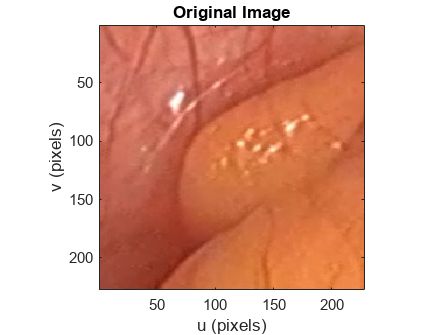

path = fullfile("images_endovideo","random","frame_left32819.png");
img = iread(path, 'uint8');
figure;
idisp(img, 'here', 'square');
title('Original Image');

## Smoothing with Gauss and Padding

- Das Bild wird mit einem Gauss-Filter geglättet.

- Das Bild wird normalisiert und in Gleitkommazahlen konvertiert und normalisiert.

- Es wird ein Padding hinzugefügt, um Randartefakte zu vermeiden.

- Die Glättungsoperation wird auf das gepaddete Bild angewendet.

- Das Ergebnis wird beschnitten, um die gepaddeten Bereiche zu entfernen.

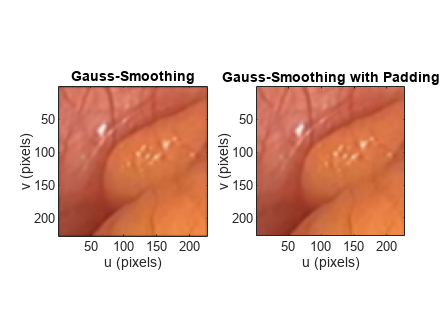

gauss = kgauss(2);
img_normalized = idouble(img) / idouble(max(img(:)));
imConv = iconvolve(img_normalized, gauss, 'same');

% Padding hinzufügen
padding = [5,5];
padded_img = padarray(img_normalized, padding, 'replicate', 'both');
imConv_padding = iconvolve(padded_img, gauss, 'same');
imConv_padding = imConv_padding(padding(1)+1:size(img,1)+padding(1), padding(1)+1:size(img,2)+padding(1), :);

figure;
subplot(121);
idisp(imConv, 'here', 'square');
title('Gauss-Smoothing');
subplot(122);
idisp(imConv_padding, 'here', 'square');
title('Gauss-Smoothing with Padding')

## **Edge Enhancement with Gaus-Filter und Padding**

- Das geglättete Bild wird zur Kantenverstärkung verwendet.

- Das Bild wird erneut gepaddet, um Randartefakte zu vermeiden.

- Das Bild wird mit einem Derivat des Gauss-Filters (DoG) gefaltet, um die Gradienten zu berechnen.

- Die Magnitude der Gradienten wird berechnet.

- Die Kantenkarte wird normalisiert.

- Das verstärkte Bild wird erhalten, indem die Kantenkarte mit dem geglätteten Bild mit einer bestimmten Stärke addiert wird.

- Die Pixelwerte werden auf den Bereich [0, 1] begrenzt.

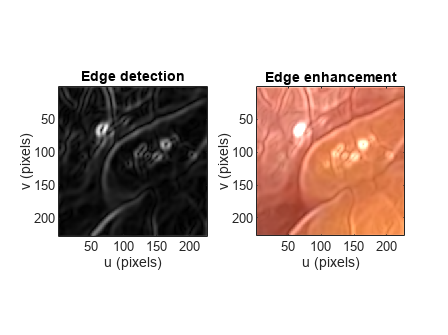

smooth_img_padded = padarray(imConv_padding, padding, 'replicate');
G = kdgauss(3)./3^2;
[Igu, Igv] = isobel(smooth_img_padded, G);
% magnitude
Imag = sqrt(Igu.^2 + Igv.^2);
% Normalize the edges
Imag = Imag ./ max(Imag(:));
Imag = Imag(padding(1)+1:size(img,1)+padding(1), padding(1)+1:size(img,2)+padding(1));
% Reinforce the edges
edge_strength = 1.5;
enhanced_img = idouble(imConv_padding) + edge_strength * Imag;
% Limit the value range to [0, 1].
enhanced_img = max(min(enhanced_img, 1), 0);

figure;
subplot(121);
idisp(Imag, 'here', 'square');
title('Edge detection');
subplot(122);
idisp(enhanced_img, 'here');
title('Edge enhancement');

## Increasing Contrasts in Image

- Das verstärkte Bild wird in den LAB-Farbraum konvertiert.

- Der maximale Helligkeitswert wird definiert.

- Der L-Kanal (Helligkeit) des LAB-Bildes wird normalisiert und histogrammausgeglichen.

- Das LAB-Bild wird zurück in den RGB-Farbraum konvertiert.

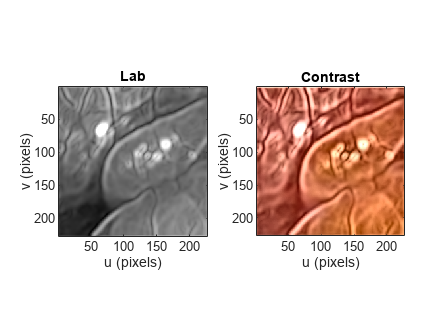

lab = colorspace('RGB->Lab', enhanced_img);
max_luminosity = 100;
L_normalized = lab(:,:,1)/max_luminosity;

contrast_img = lab;
contrast_img(:,:,1) = adapthisteq(L_normalized)*max_luminosity;
contrast_img = colorspace('Lab->RGB', contrast_img);

figure;
subplot(121);
idisp(lab(:,:,1), 'here', 'square');
title('Lab')
subplot(122);
idisp(contrast_img, 'here', 'square');
title('Contrast')

## Segmentation

### Segmentation with chromatically coordination calculation

- Das endgültige Bild (dilatiert) wird zur Segmentierung anhand der chromatischen Koordinaten verwendet. 

- Die Rot (r) und Grün (g) Kanäle werden extrahiert. 

- Histogramme der r- und g-Kanäle werden berechnet. 

- Schwellenwerte werden basierend auf den Histogrammen bestimmt, um das Bild zu segmentieren. 

- Die segmentierten Bereiche werden kombiniert, um die endgültige Maske zu erhalten.

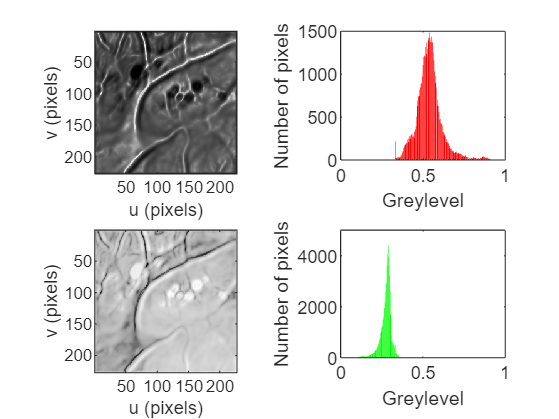

% compute the chromaticity coordinates
[r,g] = tristim2cc(contrast_img);
histogram_r = histcounts(r, 'BinLimits', [0, 1], 'BinWidth', 0.01);
threshold_r = find(histogram_r >= 1000, 1, 'last') / 100; % 0.01 entspricht der Bin-Breite
[max_pixels_r, max_index_r] = max(histogram_r);
x_value_r = (max_index_r - 1) * 0.01; % 0.01 entspricht der Bin-Breite

histogram_g = histcounts(g, 'BinLimits', [0, 1], 'BinWidth', 0.01);
threshold_g = find(histogram_g >= 1000, 1, 'first') / 100; % 0.01 entspricht der Bin-Breite
[max_pixels_g, max_index_g] = max(histogram_g);
x_value_g = (max_index_g - 1) * 0.01; % 0.01 entspricht der Bin-Breite

% Breite des Bereichs mit den meisten Grauwerten
conncomp_r = regionprops(histogram_r >= 300, 'BoundingBox');
width_r = conncomp_r(1).BoundingBox(3)/100;
conncomp_g = regionprops(histogram_g >= 300, 'BoundingBox');
width_g = conncomp_g(1).BoundingBox(3)/100;

% display histogram of r and g coordinates
figure;
subplot(221); 
idisp(r, 'here', 'square'); 
subplot(222); 
ihist(r,'r'); ax=axis; axis([0 1 ax(3:4)]);

subplot(223); 
idisp(g, 'here', 'square'); 
subplot(224); 
ihist(g,'g'); ax=axis; axis([0 1 ax(3:4)]);

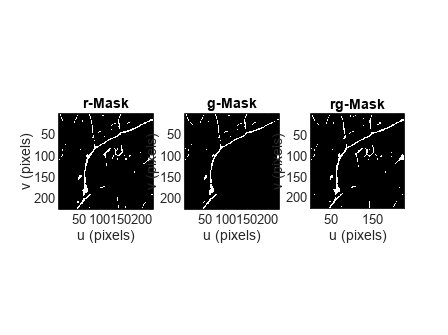


% define a mask image (true = pixel is part of object)
mask = r > x_value_r+(width_r/2);
maskr = icolor(idouble(mask));
mask = g < x_value_g-(width_g/2);
maskg = icolor(idouble(mask));
maskrg = maskr | maskg;

figure;
subplot(131); 
idisp(maskr, 'here', 'square');
title('r-Mask');
subplot(132); 
idisp(maskg, 'here', 'square');
title('g-Mask');
subplot(133); 
idisp(maskrg, 'here', 'square');
title('rg-Mask');

### Segmentation with kmeans

- Das erodierte und dilatierte Bild wird in den uint8-Format konvertiert. 

- Die Anzahl der Farben (Cluster) für die Segmentierung wird definiert. 

- K-Means-Clustering wird angewendet, um das Bild in verschiedene Regionen zu segmentieren. 

- Das gelabelte Bild wird über das Originalbild gelegt, um es zu visualisieren.

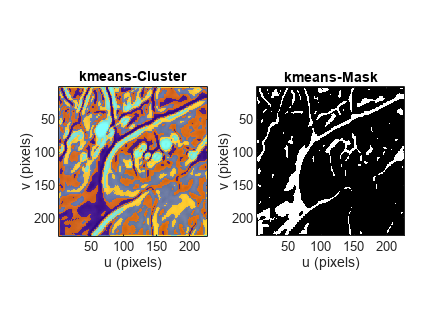

% Segmentation --> Segment Image via Kmeans
sharpened_img_int = iint(contrast_img);
numColors = 5;
L = imsegkmeans(sharpened_img_int, numColors);
B = labeloverlay(sharpened_img_int, L);

lab_img = colorspace('RGB->Lab', B);
ab = lab_img(:,:,2:3);
ab = im2single(ab);
pixel_labels = imsegkmeans(ab,numColors);
mask_kmeans = pixel_labels == 1;

figure;
subplot(121);
idisp(B, 'here', 'square');
title("kmeans-Cluster");
subplot(122);
idisp(mask_kmeans, 'here', 'square');
title("kmeans-Mask");

## Segmentation with colorkmeans

- Das endgültige Bild (dilatiert) wird zur Segmentierung mit colorkmeans verwendet. 

- Das Bild wird in eine festgelegte Anzahl von Farben (Clustern) unterteilt. 

- Die segmentierten Bereiche werden anhand der angegebenen Farblabels extrahiert.

rng('default');  % Setzen Sie den Zufallszahlengenerator auf den Standardwert
[cls, cxy] = colorkmeans(contrast_img, 6);

 1:      0.5688      0.4855      0.5008      0.5194      0.4481      0.3797 
 2:      0.3555       0.381      0.3538       0.384      0.3571      0.3576 


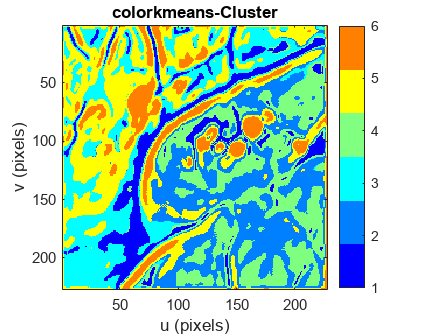

figure()
idisp(cls, 'here','colormap', 'Jet(6)', 'bar')
title("colorkmeans-Cluster");

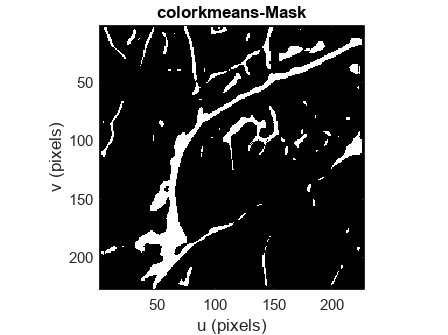


cls_i = (cls == 1);
figure()
idisp(cls_i,'here', 'square')
title("colorkmeans-Mask");

## Morphology

- Die segmentierten Bereiche werden morphologischen Operationen unterzogen.

- Ein Strukturelement (kreisförmig) wird definiert.

- Die geschlossenen Regionen (binarisiert) werden erhalten, indem die segmentierten Bereiche geschlossen werden.

- Die geschlossenen Regionen werden skelettiert, um das Ergebnis der Blutgefäßdetektion zu erhalten.

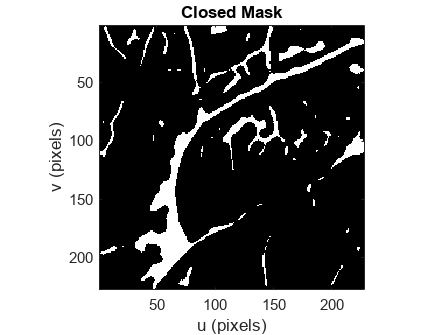

% img_binary = maskrg(:,:,1); % chromatically coordination calculation
% img_binary = mask_kmeans(:,:,1); % kmeans
img_binary = cls_i; % colorkmeans

se = kcircle(3);
closed = imbinarize(iclose(img_binary, se, 1));
figure()
idisp(closed,'here', 'square')
title("Closed Mask")

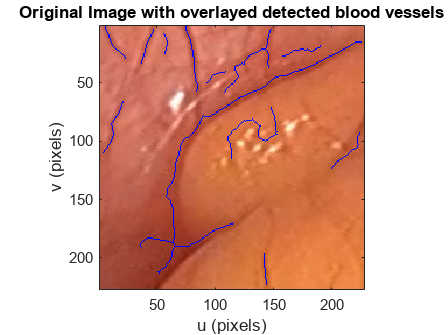

out = bwskel(closed,'MinBranchLength',15);

figure()
idisp(labeloverlay(img, out, 'Transparency', 0),'here')
title("Original Image with overlayed detected blood vessels")

## Use of Function

New Image:
 1:      0.4209      0.3168      0.3421      0.4786       0.307      0.3804 
 2:      0.3563      0.3288      0.3322      0.3646      0.3102      0.3469 


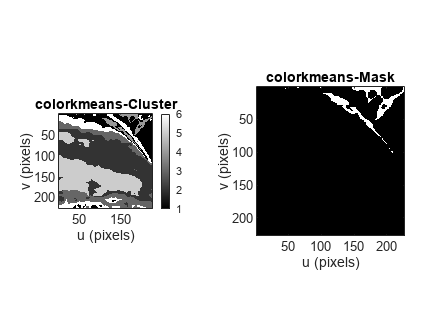

path = fullfile("images_endovideo","random","frame_left12561.png");
img1 = iread(path, 'uint8');
cls_num = 4;
blood_vessel = blood_vessel_detection(img1, cls_num);

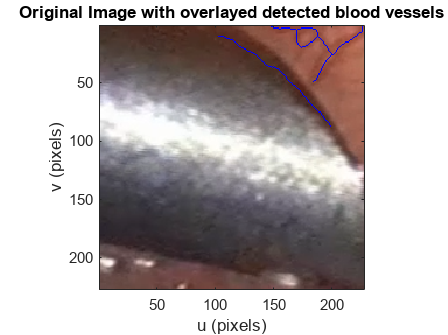

figure()
idisp(labeloverlay(img1, blood_vessel, 'Transparency', 0),'here')
title("Original Image with overlayed detected blood vessels")

New Image:
 1:      0.5538       0.478      0.5093      0.3652      0.4493      0.4144 
 2:      0.3695      0.3734      0.3729       0.345      0.3555      0.3492 


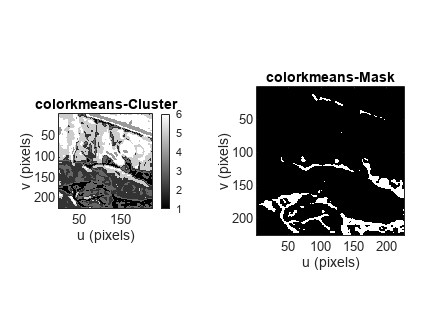


% ----------------------------------------------------------------------------------------------

path = fullfile("images_endovideo","random","frame_right22855.png");
img2 = iread(path, 'uint8');
cls_num = 1;
blood_vessel = blood_vessel_detection(img2, cls_num);

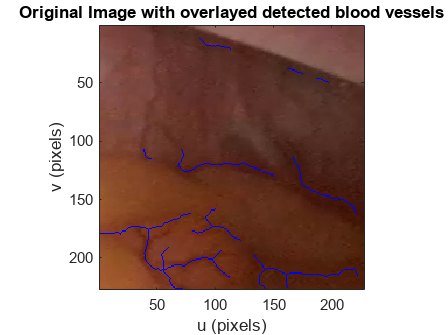

figure()
idisp(labeloverlay(img2, blood_vessel, 'Transparency', 0),'here')
title("Original Image with overlayed detected blood vessels")

New Image:
 1:       0.387      0.4124      0.5043       0.436      0.4644      0.4632 
 2:      0.3446      0.3495      0.3606      0.3548      0.3871      0.3548 


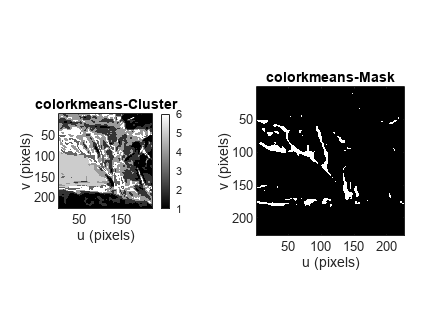


% ----------------------------------------------------------------------------------------------

path = fullfile("images_endovideo","random","frame_right22581.png");
img3 = iread(path, 'uint8');
cls_num = 3;
blood_vessel = blood_vessel_detection(img3, cls_num);

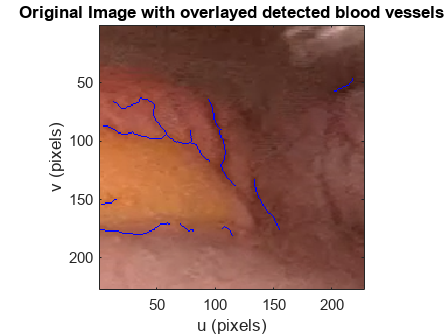

figure()
idisp(labeloverlay(img3, blood_vessel, 'Transparency', 0),'here')
title("Original Image with overlayed detected blood vessels")

## Function

function blood_vessel = blood_vessel_detection(img, cls_num)
    % smoothing
    disp("New Image:");
    img_normalized = idouble(img) / idouble(max(img(:)));
    g = kgauss(2);
    padding = [5,5];
    padded_img = padarray(img_normalized, padding, 'replicate', 'both');
    imConv = iconvolve(padded_img, g, 'same');
    smooth_img = imConv(padding(1)+1:size(img,1)+padding(1), padding(1)+1:size(img,2)+padding(1), :);
    % edge enhancement
    smooth_img_padded = padarray(smooth_img, padding, 'replicate');
    gauss = 2;
    G = kdgauss(gauss)./gauss^2;
    [Igu, Igv] = isobel(smooth_img_padded, G);
    Imag = sqrt(Igu.^2 + Igv.^2);
    Imag = Imag ./ max(Imag(:));
    Imag = Imag(padding(1)+1:size(img,1)+padding(1), padding(1)+1:size(img,2)+padding(1));
    edge_strength = 1.5;
    enhanced_img = idouble(smooth_img) + edge_strength * Imag;
    enhanced_img = max(min(enhanced_img, 1), 0);
    % contrasts
    lab = colorspace('RGB->Lab', enhanced_img);
    max_luminosity = 100;
    L_normalized = lab(:,:,1)/max_luminosity;
    
    contrast_img = lab;
    contrast_img(:,:,1) = adapthisteq(L_normalized)*max_luminosity;
    contrast_img = colorspace('Lab->RGB', contrast_img);
    % segmentation
    rng('default');
            % numColors = 4;
    [cls, ~] = colorkmeans(contrast_img, 6);
    cls_i = (cls == cls_num);
    figure()
    subplot(121)
    idisp(cls, 'here','colormap', 'Jet(6)', 'bar')
    title("colorkmeans-Cluster")
    subplot(122)
    idisp(cls_i,'here', 'square')
    title("colorkmeans-Mask")

    % Morphology
    se = kcircle(4);
    closed = imbinarize(iclose(cls_i, se));
    blood_vessel = bwskel(closed,'MinBranchLength',10);
end